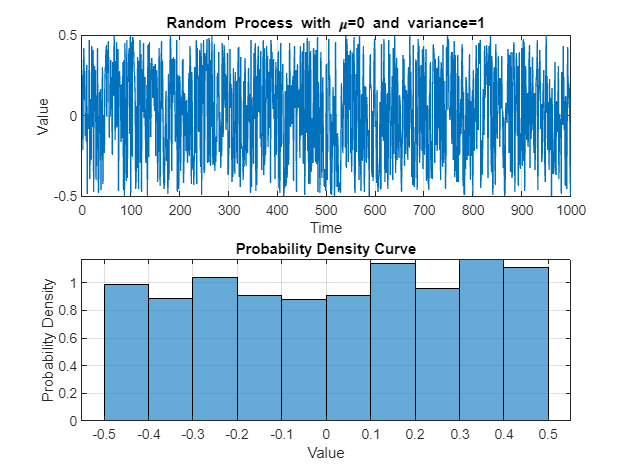

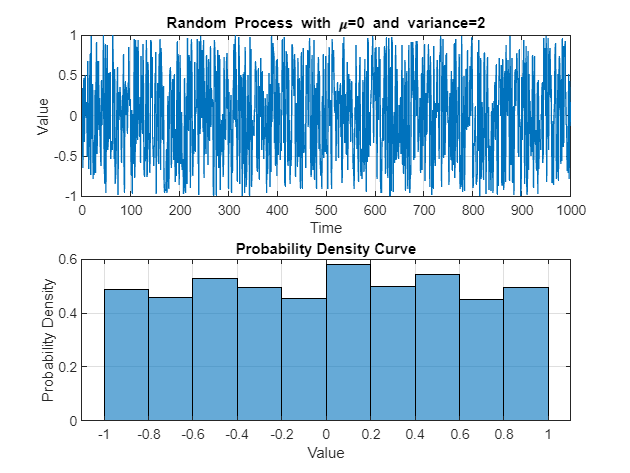

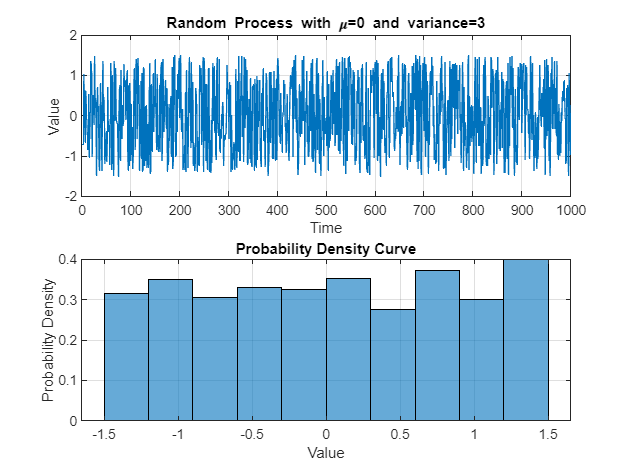

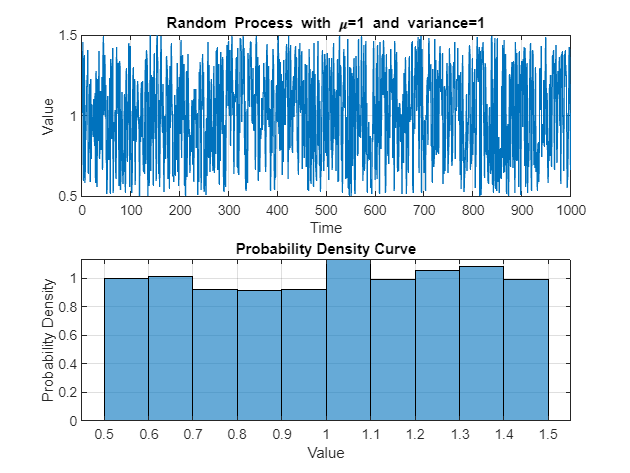

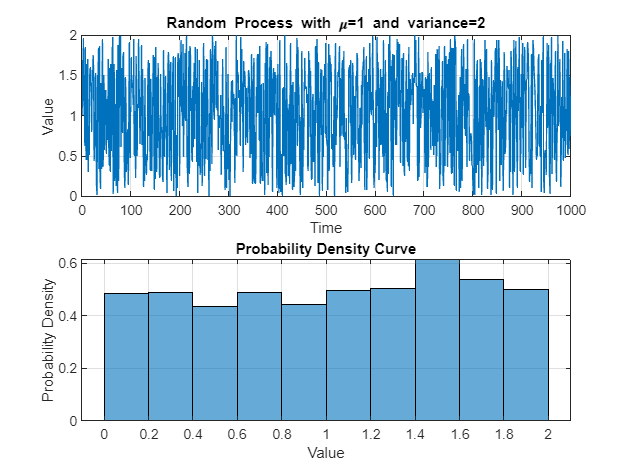

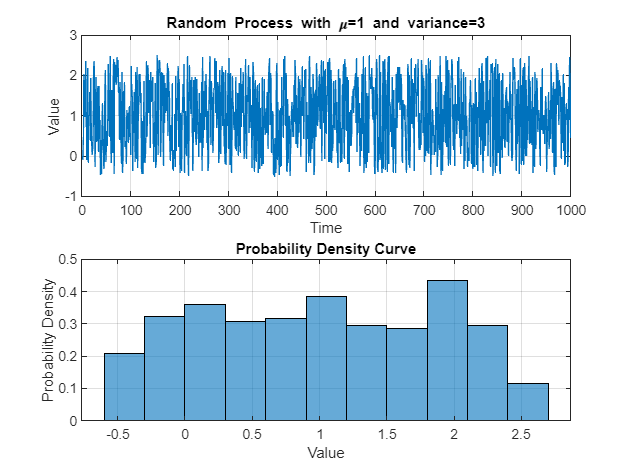

clear all; close all; clc;

% Parameters
num_samples = 1000;  % Number of samples
mean_values = [0, 0, 0, 1, 1, 1];  % Different mean values
variance_values = [1, 2, 3, 1, 2, 3];  % Different variance values

% Generate the time axis (x-axis)
time_axis = 1:num_samples;

% Initialize matrix to store simulation data
num_simulations = length(mean_values);
simulation_data = zeros(num_simulations, num_samples);

% Loop through different mean and variance values
for i = 1:num_simulations
    mean_val = mean_values(i);
    variance = variance_values(i); % Using the variance value as the range for uniform distribution
    
    % Generate random samples from a uniform distribution within the specified range
    random_samples = variance * (rand(1, num_samples) - 0.5) + mean_val;
    simulation_data(i, :) = random_samples;

    % Create a new figure for each random process
    figure;

    % Plot the random process
    subplot(2, 1, 1);
    plot(time_axis, random_samples);
    xlabel('Time');
    ylabel('Value');
    title(['Random Process with \mu=', num2str(mean_val), ' and variance=', num2str(variance)]);
    grid on;

    % Plot the histogram and probability density curve
    subplot(2, 1, 2);
    histogram(random_samples, 'Normalization', 'pdf');
    xlabel('Value');
    ylabel('Probability Density');
    title('Probability Density Curve');
    grid on;
end


% Calculate Time Averages and Variances for each simulation
time_averages = mean(simulation_data, 2);
variances = var(simulation_data, 0, 2);

% Display Time Averages and Variances for each simulation
disp('Time Averages and Variances for each simulation:');

Time Averages and Variances for each simulation:


for sim = 1:num_simulations
    fprintf('Simulation %d - Time Average: %f, Variance: %f\n', sim, time_averages(sim), variances(sim));
end

Simulation 1 - Time Average: 0.016643, Variance: 0.086960
Simulation 2 - Time Average: 0.002316, Variance: 0.329511
Simulation 3 - Time Average: 0.030596, Variance: 0.776681
Simulation 4 - Time Average: 1.007712, Variance: 0.083500
Simulation 5 - Time Average: 1.027138, Variance: 0.334084
Simulation 6 - Time Average: 1.009716, Variance: 0.748596



% Calculate Ensemble Averages for specific time instances
time_instants = [1, 100, 1000]; % Specific time instances for analysis
ensemble_averages = mean(simulation_data(:, time_instants), 1);

% Display Ensemble Averages
disp('Ensemble Averages:');

Ensemble Averages:


for i = 1:length(time_instants)
    fprintf('At time instance %d: %f\n', time_instants(i), ensemble_averages(i));
end

At time instance 1: 0.429959
At time instance 100: 0.028048
At time instance 1000: 0.176949
